attractor1 = readtable("attractor_1.xlsx");

attractor2 = readtable("attractor_2.xlsx");


x_1 = attractor1.Amplitude_Plot0(1:10000);
x_2 = attractor2.Amplitude_Plot0(1:10000);
y_1 = attractor1.Amplitude_Plot1(1:10000);
y_2 = attractor2.Amplitude_Plot1(1:10000);
z_1 = attractor1.Amplitude_Plot2(1:10000);
z_2 = attractor2.Amplitude_Plot2(1:10000);

V = matrix();
x_3 = -15:0.1:14.9;
y_3 = -14:0.1:13.9;
z_3 = -2:0.1:38;

color_0 = [0.9290 0.6940 0.1250];
color_1 = [0 0.4470 0.7410];
colo2_2 = [1 0 0];
color_3 = [0.4940 0.1840 0.5560];

% отрисовка
figure;
map = [
    color_0
    color_1
    color_0
    color_1
    ];

h = matrix;
x =1.4

x = 1.4000

y = -2

y = -2

z = 0

z = 0

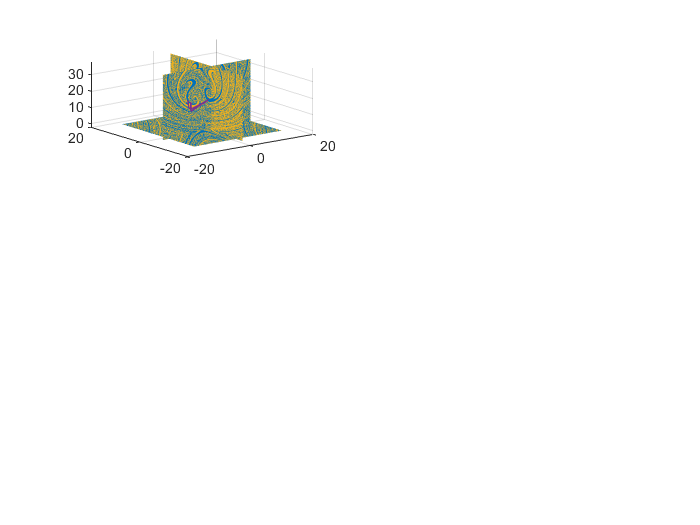


colormap(map);
tiledlayout(3,2);
nexttile;
%slice(V, )

s = slice(y_3, x_3, z_3, V, x, y, z);
set(s, 'EdgeColor','none');

hold on;
h(2) = plot3(y_1, x_1, z_1, 'Color', color_3);

h(3) = plot3(y_2, x_2, z_2, 'Color', color_2);

Unrecognized function or variable 'color_2'.

hold off;


function [V] = matrix() % скрипт для создания матрицы
x = 300;
y = 280;
z = 401;

str = int2str(z);
n = strlength(str);

V = zeros(x,y,z);

for i = 1:z
    pStr = 'D:\3d\';
    m = floor(log10(i))+1;
    if m < n
        for j = m:n-1
            pStr = strcat(pStr,'0');
        end
    end
    pStr = strcat(pStr,sprintf('%d.txt',i));
    V(:,:,i) = dlmread(pStr);
end
end